# **Welcome to Deci**

**A fluid pipeline to analyze EEG Data with ease**

Written and Compiled by @John Nguyen of Robert Reinhart Lab on 10/15/2018, contact: Akida@bu.edu

## 0. MainMenu

Deci = [];
Deci.Folder.Raw         = ['C:\Users\User\Desktop\John\Newstru\Newstru2\RawData'];    
Deci.SubjectList = 'gui';  
Deci.Step               = 5;
Deci.Proceed            = true;  
Deci.PCom               = false;                           % Activates Parallel Computing (if availible)
Deci.Folder.Version     = ['C:\Users\User\Desktop\John\Newstru\Newstru2\ProcessedData'];    

## 1. Trial Definitions

    Deci.DT.Type = 'Manual';             
    Deci.DT.Starts     = {9};         %Cell Array of Markers for ETs Start.
    Deci.DT.Ends       = {10};         %Cell Array of Markers for ETs End.
    Deci.DT.Markers    = {[20 21 23 24] [27 28] [31 32] [51 52]};   
    Deci.DT.Locks      = [14 30 50];
    Deci.DT.Toi        = [-2 3]; 
    
    Deci.DT.Block.Start = {11};
    Deci.DT.Block.End = {12};
    Deci.DT.Block.Markers = [];

## 2. PreProcessing Steps

Deci.PP.Demean              = [-.5 -.2];        % [Beg End], Secs Relative to .DT.Locks, Baseline Window for Correction.

## 3. Artifact Rejection

Deci.Art.crittoilim = [-.5 1.5];  
Deci.Art.bpf = [1 80];

## 4. Analysis

#### General Set-Up

Deci.Analysis.Laplace            =true;                   % Leave .Laplace as 0 to not do a Laplacian Transformation based on file realistic_1005.txt format
Deci.Analysis.Locks = [1 2 3]; 
Deci.Analysis.DownSample = 500;

#### Time-Frequency Analysis

Deci.Analysis.Freq.method        = 'wavelet';    % Currently only uses Wavelet Decomp
Deci.Analysis.Freq.foi           = exp(linspace(log(4),log(40),20));       % Frequency of Interest
Deci.Analysis.Freq.width         = 7 ;           % Width
Deci.Analysis.Freq.gwidth        = 3;            % Gwidth
Deci.Analysis.Freq.Toi           = [-.5 1.5];       % Time Range
Deci.Analysis.Freq.Toilim        = [-2 3]; 

Deci.Analysis.Var =false;
Deci.Analysis.Clean = true;

## 5. Plotting

    Deci.Plot.Lock = '3';
    Deci.Plot.Conditions = {[20 31 51] [21 31 51] [23 31 51] [24 31 51] [20 31 52] [21 31 52] [23 31 52] [24 31 52] ...
                            [20 32 51] [21 32 51] [23 32 51] [24 32 51] [20 32 52] [21 32 52] [23 32 52] [24 32 52]};
    Deci.Plot.Var = false;
    Deci.Plot.GA = true;

#### Math

Deci.Plot.Math.Form = {'[x1+x2]/2','[x5+x6]/2','[x4+x12]/2','[x8+x16]/2' '[x1+x2+x13+x15]/4' '[x5+x6+x9+x10]/4'};   
%Deci.Plot.Math.Type = 0;


#### Conditions

Deci.Plot.Draw = {[1:16] [17 18] [19 20] [21 22] [3 6]};
Deci.Plot.Title = {'All trials' 'Opt Choices' 'non-valence Expectation' 'valenced expectation' 'traditional instrumental'};
Deci.Plot.Subtitle = {{'G_BTE' 'g_BTE' 'Z_BTE' 'Y_BTE' 'G_WTE' 'g_WTE' 'Z_WTE' 'Y_WTE' ...
                       'N_BTE' 'n_BTE' '0_WTE' 'X_WTE' 'N_WTE' 'n_WTE' '0_BTE' 'X_BTE'} {'+RPE' '-PPE'} {'Expected' 'Unexpected'} {'Expected' 'Unexpected'} ...
                       {'g' 'n'}};
Deci.Plot.Figures = [false false false false true];

#### Time-Frequency

%Deci.Plot.Freq.Foi = [];
Deci.Plot.Freq.Foi = [4 8];
Deci.Plot.Freq.Toi = [];
Deci.Plot.Freq.Channel = {'FCz'};
Deci.Plot.Freq.Type = 'TotalPower';     % Use 'TotalPower','ITPC' or 'EvokedPower'

Deci.Plot.Freq.Bsl = [-.5 -.2];           % Baseline Correction Time
Deci.Plot.Freq.Roi = 'maxabs';          % use 'maxmin','maxabs or [min max] to set.
Deci.Plot.Freq.BslType ='db';    % Use 'absolute','relative','relchange','db','normchange'

Deci.Plot.Freq.Topo =1;
Deci.Plot.Freq.Square =1;

Deci.Plot.Freq.Wires.avg =  'freq';


#### Behavioral

Deci.Plot.Behv = [];
Deci.Plot.Behv.Source = 'Definition';

Deci.Plot.Behv.Acc.Total = {[1 2 5 6 9 10 13 14] [3 7 11 15] [4 8 12 16]};
Deci.Plot.Behv.Acc.Subtotal = {[1 2 5 6] [3 7] [4 8]};
Deci.Plot.Behv.Acc.Title = {'Traditional GN' 'OZ' 'XY'};
Deci.Plot.Behv.Acc.Subtitle = {'Percent Choice Opt' 'Percent 0' 'Percent X'};

Deci.Plot.Behv.Acc.Block = [1:6];
Deci.Plot.Behv.Acc.Collapse.Trial =false;
Deci.Plot.Behv.Acc.Collapse.Block = true;
Deci.Plot.Behv.Acc.Collapse.Subject = false;
Deci.Plot.Behv.Acc.Collapse.Uneven = 'maxlength:nans';
Deci.Plot.Behv.Acc.Collapse.Movmean =  true;

Deci.Plot.Behv.RT.Draw = {[1 2 5 6] [9 10 13 14] [3 7] [11 15] [4 8] [12 16]};
Deci.Plot.Behv.RT.Title = {'Gg RT' 'Nn RT' '0 RT' 'X RT' 'Z RT' 'Y RT'};
Deci.Plot.Behv.RT.Subtitle = {'Opt' 'Worst'};
Deci.Plot.Behv.RT.Locks = [1 2];

Deci.Plot.Behv.RT.Block = [1:6];
Deci.Plot.Behv.RT.Collapse.Trial =false;
Deci.Plot.Behv.RT.Collapse.Block = true;
Deci.Plot.Behv.RT.Collapse.Subject = false;
Deci.Plot.Behv.RT.Collapse.Uneven = 'maxlength:nans';

Options

Deci.Run.Behavior = false;
Deci.Run.Freq =true;
Deci.Run.ERP =false;
Deci.Run.CFC = false;

## ** 6. Run**

Channel FCz of 1
Elapsed time is 0.753110 seconds.
Channel FCz of 1
Elapsed time is 0.728398 seconds.
Channel FCz of 1
Elapsed time is 0.734933 seconds.
Channel FCz of 1
Elapsed time is 0.618337 seconds.
computing average powspctrm over 4 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 4 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 4 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 4 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 4 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 4 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 4 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 4 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 4 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 4 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 4 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 4 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 4 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 4 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 4 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 4 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 4 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 4 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 4 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 4 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 4 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 4 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 4 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 4 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 4 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 4 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 4 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 4 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 4 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 4 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 4 subjects


the call to "ft_freqgrandaverage" took 0 seconds
computing average powspctrm over 4 subjects


the call to "ft_freqgrandaverage" took 0 seconds
selecting powspctrm from the first input argument
the call to "ft_math" took 0 seconds
selecting powspctrm from the first input argument
the call to "ft_math" took 0 seconds
selecting powspctrm from the first input argument
the call to "ft_math" took 0 seconds
selecting powspctrm from the first input argument
the call to "ft_math" took 0 seconds
selecting powspctrm from the first input argument
the call to "ft_math" took 0 seconds
selecting powspctrm from the first input argument
the call to "ft_math" took 0 seconds
selecting powspctrm from the first input argument
the call to "ft_math" took 0 seconds
selecting powspctrm from the first input argument
the call to "ft_math" took 0 seconds
selecting powspctrm from the first input argument
the call to "ft_math" took 0 seconds
selecting powspctrm from the first input argument
the call to "ft_math" took 0 seconds
selecting powspctrm from the first input argument
the call to "ft_math" took 0 se

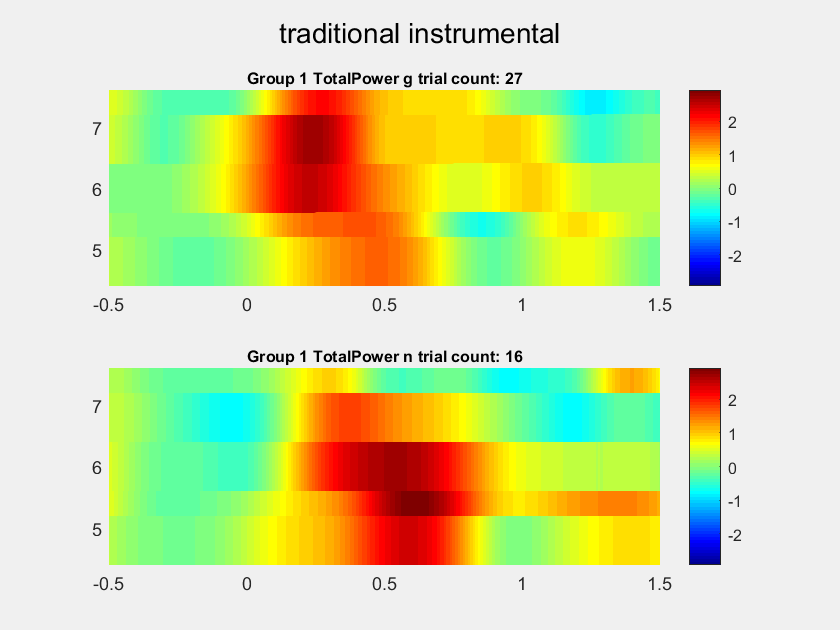

the call to "ft_singleplotTFR" took 1 seconds


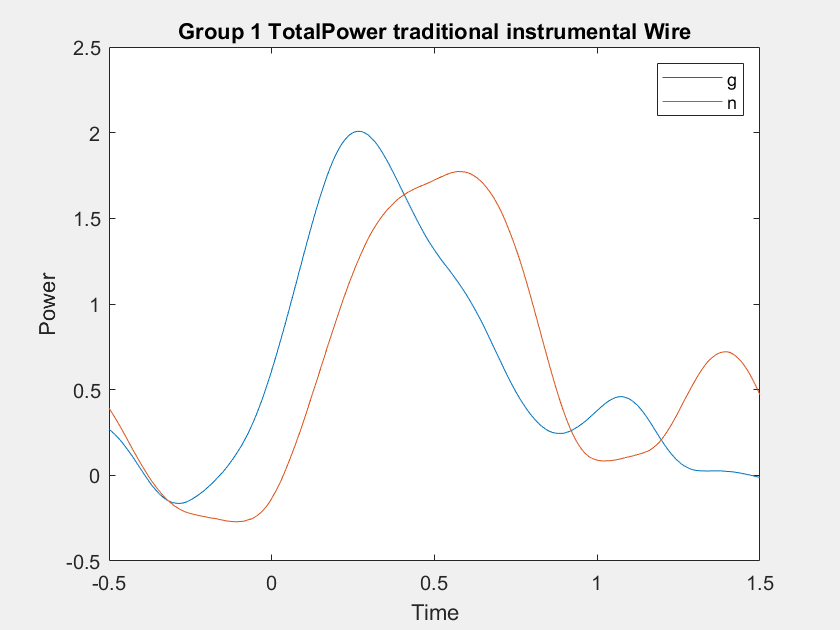

the call to "ft_singleplotTFR" took 0 seconds



Deci_Backend(Deci);